# Kahan-family-optimal solution of OCI: Example 3.2

**Description**: Code to produce Example 3.2 of [1].

**Outputs**: none

**Assumptions and limitations**: none

**Other m-files required**: plotCov2.m, overlappingCI.m

**MAT-files required**: none

**Toolboxes required**: YALMIP [2], SDPT3 [3,4]

**Authors**: Leonardo Pedroso, Pedro Batista, W.P.M.H. (Maurice) Heemels

**Revision history**:

- 20/01/2025 - First draft of full implementation (Leonardo Pedroso)

**References**:

[1] L. Pedroso, P. Batista, and W.P.M.H. Heemels, "Overlapping Covariance Intersection: Fusion with Partial Structural Knowledge of Correlation from Multiple Sources", 2025. (submitted)

[2] J. Lofberg, "YALMIP: A toolbox for modeling and optimization in MATLAB." In 2004 IEEE international conference on robotics and automation, pp. 284-289, 2004.

[3] K.C. Toh, M.J. Todd, and R.H. Tutuncu, SDPT3 — a Matlab software package for semidefinite programming, Optimization Methods and Software, 11 (1999), pp. 545–581.

[4] R.H Tutuncu, K.C. Toh, and M.J. Todd, Solving semidefinite-quadratic-linear programs using SDPT3, Mathematical Programming Ser. B, 95 (2003), pp. 189–217.

## Initialization

clear;
epsl = 1e-5;
% Colorblind-safe color palette (Wong, B. Points of view: Color blindness.
% Nat Methods 8,441 (2011). https://doi.org/10.1038/nmeth.1618)
color.black = [0 0 0]/255;
color.orange = [230 159 0]/255;
color.cyan = [86 180 233]/255;
color.green = [0 158 115]/255;
color.yellow = [240 228 66]/255;
color.blue = [0 114 178]/255;
color.red = [213 94 0]/255;
color.pink = [204 121 167]/255;


## Example 2D

% Seed
seed = 62038;
rng(seed);

% Sizes
n = 1;
m = 2;
o = 2; %(<= m)

% Generate bounds
M = 3;
Xb = cell(M,1);
Wb = cell(M,1);
Yb = cell(M,1);

% 1. Normal bound (X<= Xb1)
Xb{1,1} = 2*(rand(2,2)-0.5);
Xb{1,1} = Xb{1,1}*Xb{1,1}';
% In this case it is the same as Y1 = inv(X1)
Wb{1,1} = eye(2);
Yb{1,1} = (Wb{1,1}'/Xb{1,1})*Wb{1,1};

% 2. Bound on an principal component (X_11 <= Xb2_11)
Wb{2,1} = [1 0];
Xb{2,1} = (rand(1,1)-0.5);
Xb{2,1} = Xb{2,1}*Xb{2,1}';
% Equivalent to
% X2 = [1 0;
%       0 +inf]
Yb{2,1} = (Wb{2,1}'/Xb{2,1})*Wb{2,1};

% 3. Bound on an nonprincipal component (X_11 <= Xb2_11)
Wb{3,1} = [2 -1];
Xb{3,1} = 6*(rand(1,1)-0.5);
Xb{3,1} = Xb{3,1}*Xb{3,1}';
Yb{3,1} = (Wb{3,1}'/Xb{3,1})*Wb{3,1};

% Generate matrices H,C,R
H = 2*(rand(o,n)-0.5);
C = 2*(rand(o,m)-0.5);
R = 2*(rand(o,o)-0.5);
R = R*R';

% Overlapping CI
[KOCItr,BOCItr,YOCItr,UOCItr] = overlappingCI(H,R,C,Yb,'trace');


 num. of constraints =  5
 dim. of sdp    var  =  5,   num. of sdp  blk  =  2
 dim. of linear var  =  8
 dim. of free   var  =  1
 *** convert ublk to linear blk
********************************************************************************************
   SDPT3: homogeneous self-dual path-following algorithms
********************************************************************************************
 version  predcorr  gam  expon
   HKM      1      0.000   1
it pstep dstep pinfeas dinfeas  gap     mean(obj)    cputime    kap   tau    theta
--------------------------------------------------------------------------------------------
 0|0.000|0.000|2.3e+02|1.7e+00|3.5e+04| 5.572638e+03| 0:0:00|3.5e+04|1.0e+00|1.0e+00| chol 1  1 
 1|0.049|0.049|2.2e+02|1.7e+00|3.6e+04| 5.705559e+03| 0:0:00|3.5e+04|1.0e+00|9.9e-01| chol 1  1 
 2|0.222|0.222|2.0e+02|1.5e+00|3.5e+04| 5.165130e+03| 0:0:00|2.9e+04|9.6e-01|8.5e-01| chol 1  1 
 3|0.832|0.832|5.3e+01|4.0e-01|8.5e+03| 1.111777e+03| 0:0:00|7.6e+

[KOCIdet,BOCIdet,YOCIdet,UOCIdet] = overlappingCI(H,R,C,Yb,'det');


 num. of constraints =  5
 dim. of sdp    var  =  5,   num. of sdp  blk  =  2
 dim. of linear var  =  9
 dim. of free   var  =  1 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|4.5e+02|1.5e+00|4.0e+04| 1.172531e+04  5.081767e+00| 0:0:00| chol  1  1 
 1|0.608|0.236|1.8e+02|1.1e+00|3.7e+04| 7.408465e+03  5.107417e+00| 0:0:00| chol  1  1 
 2|0.812|0.702|4.8e+01|3.3e-01|1.1e+04| 3.293027e+03  4.147943e+00| 0:0:00| chol  1  1 
 3|0.927|0.671|4.5e+01|1.1e-01|3.2e+03| 4.839451e+02  3.857241e+00| 0:0:00| chol  1  1 
 4|0.233|0.649|3.2e+01|3.8e-02|1.3e+03| 4.060736e+02  3.148535e+00| 0:0:00| chol 


KOCItr

KOCItr =     2.1535   -3.9684


KOCIdet

KOCIdet =     2.1535   -3.9684


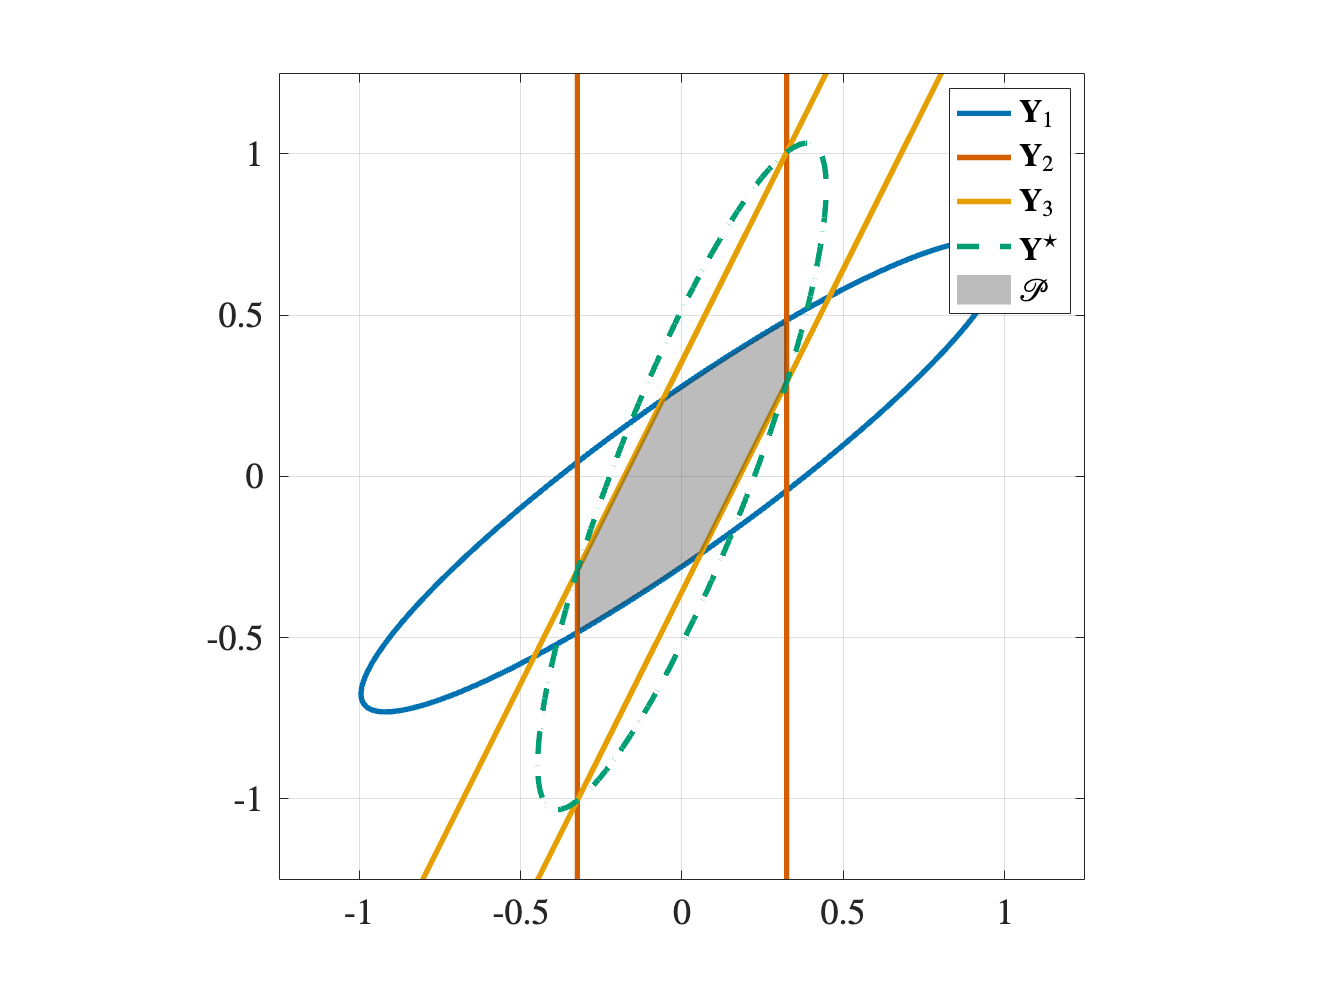


% Plot elipsoids
elpsXb1 = plotCov2(Yb{1,1});
elpsXb2 = plotCov2(Yb{2,1}+epsl*eye(2));
elpsXb3 = plotCov2(Yb{3,1}+epsl*eye(2));
elpsOCItr = plotCov2(YOCItr+epsl*eye(2));
elpsOCIdet = plotCov2(YOCIdet+epsl*eye(2));

poly1 = polyshape(elpsXb1(1,1:end-1),elpsXb1(2,1:end-1));
poly2 = polyshape(elpsXb2(1,1:end-1),elpsXb2(2,1:end-1));
poly3 = polyshape(elpsXb3(1,1:end-1),elpsXb3(2,1:end-1));
intersect12 = intersect(poly1, poly2);
intersect123 = intersect(intersect12, poly3);
figure('Position',4*[0 0 192 144]); % Nice aspect ratio for double column
hold on;
grid on;
box on;
set(gca,'FontSize',20);
set(gca,'TickLabelInterpreter','latex') % Latex style axis
plot(elpsXb1(1,:),elpsXb1(2,:),'LineWidth',3,'Color',color.blue);
plot(elpsXb2(1,:),elpsXb2(2,:),'LineWidth',3,'Color',color.red);
plot(elpsXb3(1,:),elpsXb3(2,:),'LineWidth',3,'Color',color.orange);
plot(elpsOCItr(1,:),elpsOCItr(2,:),'LineWidth',3,'Color',color.green,'LineStyle','--');
%plot(elpsOCIdet(1,:),elpsOCIdet(2,:),'LineWidth',3,'Color',color.green,'LineStyle','--');
plot(intersect123, 'FaceColor', 0.25*[1 1 1], 'EdgeColor', 'none');
legend({'$\mathbf{Y}_1$','$\mathbf{Y}_2$','$\mathbf{Y}_3$','$\mathbf{Y}^\star$','$\mathcal{P}$'},'Interpreter','latex')
axis equal;
lim_axis = 0.25*max([max(elpsXb1(1,:)) max(elpsXb1(2,:))])+1;
xlim(lim_axis*[-1 1]);
ylim(lim_axis*[-1 1]);


% Save figure to .fig and .png formats
% savefig('./figures/eg2_2D.fig');
% set(gcf,'renderer','Painters');
% exportgraphics(gcf,'./figures/eg2_2D.pdf');